clear, clc;
syms a b d_x % 这里的a = k*\d_x, b是一个超参

% ------j-3------j-2-----j-1-------j--------j+1-------j+2--------

% 在j点处泰勒展开，则有如下关系，其中d_x为网格尺寸，b为超参
% A @ [a_1, a_2, a_3, a_4, a_5, a_6].T = b
% 写成增广矩阵形式：
A_b = [[  1,  1,  1, 1, 1, 1, 0]
[ -3, -2, -1, 0, 1, 2, 1/d_x]
[  9,  4,  1, 0, 1, 4,     0]
[-27, -8, -1, 0, 1, 8,     0]
[ 81, 16,  1, 0, 1, 16,     0]
[  0,  0,  0, 1, 0, 0, b/d_x]];

% 求解A_b
B = rref(A_b);
B = B(:,7)*d_x; % 此时A @ x = b的解就是 B/d_x，这里乘上d_x是为了后续计算方便
disp(B)

$$\left(\begin{array}{c} -\frac{b}{10}\\ \frac{b}{2}+\frac{1}{12}\\ -b-\frac{2}{3}\\ b\\ \frac{2}{3}-\frac{b}{2}\\ \frac{b}{10}-\frac{1}{12} \end{array}\right)$$


% 因此u_x(j) = A(1,:) @ B /d_x
% 令u(j) = exp(ikj)
% K = B(1)*exp(-3ia) + B(2)*exp(-2ia) -B(3)*exp(-ia) + B(4) + B(5)*exp(ia) + B(6)*exp(2ia),
% 耗散误差：K_r = real(K), 色散误差：K_i = imag(K)
K = B(1)*exp(-3*i*a) + B(2)*exp(-2*i*a) + B(3)*exp(-i*a) + B(4) + B(5)*exp(i*a) + B(6)*exp(2*i*a);
K_r = real(K);
K_i = imag(K);

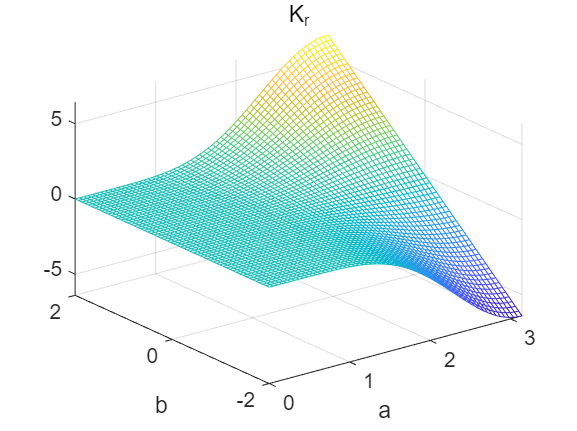

% 绘制K_r,K_i关于a和b的图像
figure()
ezmesh(K_r, [0 pi -2 2])
title('K_r')

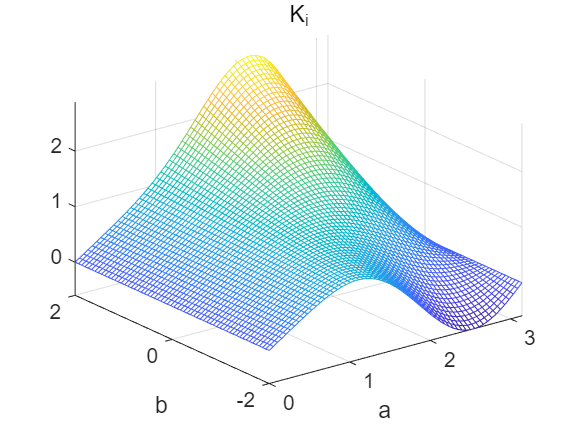


figure()
ezmesh(K_i, [0 pi -2 2])
title('K_i')

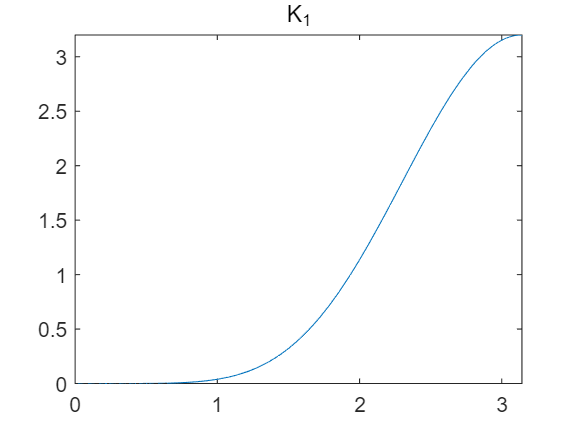

% 令b=1似乎是不错
K_r_1 = subs(K_r, b, 1);
K_i_1 = subs(K_i, b, 1);

figure()
fplot(K_r_1, [0 pi])
title('K_r_1')

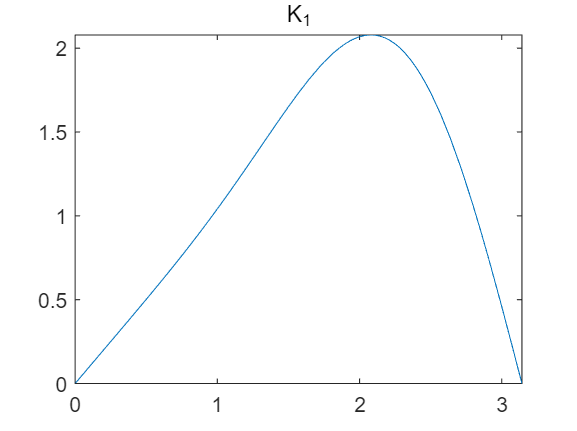


figure()
fplot(K_i_1, [0 pi])
title('K_i_1')

% 此时的系数为
disp('b = 1时，差分格式的系数为')

b = 1时，差分格式的系数为


b_ = subs(B,b,1)/d_x;
disp(b_)

$$\left(\begin{array}{c} -\frac{1}{10\,d_{x}}\\ \frac{7}{12\,d_{x}}\\ -\frac{5}{3\,d_{x}}\\ \frac{1}{d_{x}}\\ \frac{1}{6\,d_{x}}\\ \frac{1}{60\,d_{x}} \end{array}\right)$$


% 计算截断误差的系数(泰勒展开五阶)
t = ([-3 -2 -1 0 1 2]*d_x); % 即相应的d_t
for i = 1:5
    disp(t.^i * b_ )
end

$$1$$

$$0$$

$$0$$

$$0$$

$$8\,{d_{x}}^{4}$$